%% Chaff Distribution in 3D
% This script generates and visualizes 3D distributions of chaff particles.
% Distributions include Uniform, Gaussian, and Monte Carlo Sampling.
% All parameters are adjustable for flexibility and experimentation.


%% Parameters
% Number of particles
numParticles = 1000;

% Uniform Distribution Bounds
xBounds = [-10, 10];
yBounds = [-10, 10];
zBounds = [0, 20];

% Gaussian Distribution Parameters
mu = [0, 0, 10]; % Mean (x, y, z)
sigma = [5, 5, 2]; % Standard deviation (x, y, z)

% Monte Carlo Distribution Bounds
mcBounds = xBounds; % Assuming same bounds for simplicity

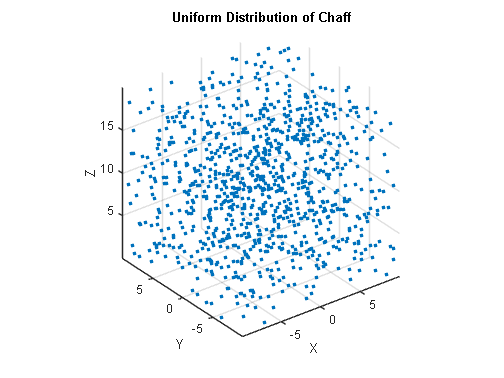

%% Uniform Distribution
% Generate uniform distribution
xUniform = xBounds(1) + (xBounds(2) - xBounds(1)) * rand(numParticles, 1);
yUniform = yBounds(1) + (yBounds(2) - yBounds(1)) * rand(numParticles, 1);
zUniform = zBounds(1) + (zBounds(2) - zBounds(1)) * rand(numParticles, 1);

% Visualise
figure;
scatter3(xUniform, yUniform, zUniform, 10, 'filled');
title('Uniform Distribution of Chaff');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;

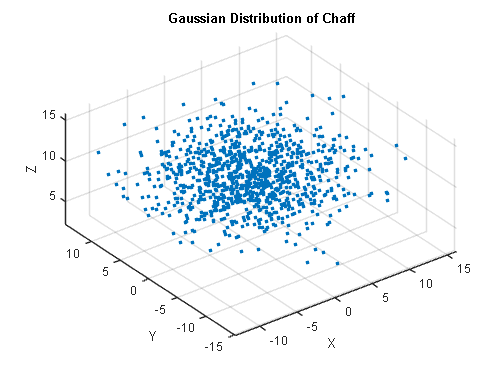

%% Gaussian Distribution
% Generate Gaussian distribution
xGaussian = mu(1) + sigma(1) * randn(numParticles, 1);
yGaussian = mu(2) + sigma(2) * randn(numParticles, 1);
zGaussian = mu(3) + sigma(3) * randn(numParticles, 1);

% Visualise
figure;
scatter3(xGaussian, yGaussian, zGaussian, 10, 'filled');
title('Gaussian Distribution of Chaff');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;

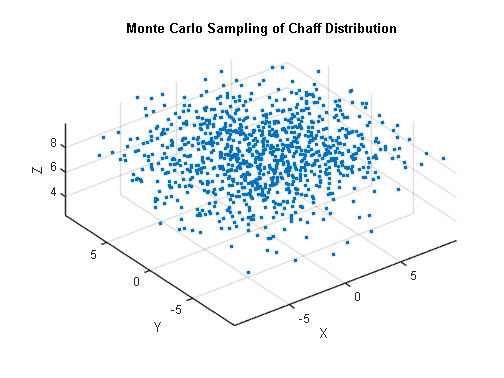

%% Monte Carlo Sampling
% Define a custom PDF (truncated Gaussian)
customPDF = @(x, y, z) exp(-((x - mu(1)).^2 / (2 * sigma(1)^2) + ...
                             (y - mu(2)).^2 / (2 * sigma(2)^2) + ...
                             (z - mu(3)).^2 / (2 * sigma(3)^2)));

% Monte Carlo rejection sampling
xMC = []; yMC = []; zMC = [];
while length(xMC) < numParticles
    xTrial = mcBounds(1) + (mcBounds(2) - mcBounds(1)) * rand;
    yTrial = mcBounds(1) + (mcBounds(2) - mcBounds(1)) * rand;
    zTrial = mcBounds(1) + (mcBounds(2) - mcBounds(1)) * rand;
    pdfValue = customPDF(xTrial, yTrial, zTrial);
    if rand < pdfValue % Accept with probability proportional to PDF value
        xMC = [xMC; xTrial];
        yMC = [yMC; yTrial];
        zMC = [zMC; zTrial];
    end
end

% Visualise
figure;
scatter3(xMC, yMC, zMC, 10, 'filled');
title('Monte Carlo Sampling of Chaff Distribution');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;

%% Combined Visualisation
figure;

% Uniform
subplot(1, 3, 1);
scatter3(xUniform, yUniform, zUniform, 10, 'filled');
title('Uniform Distribution');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;

% Gaussian
subplot(1, 3, 2);
scatter3(xGaussian, yGaussian, zGaussian, 10, 'filled');
title('Gaussian Distribution');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;

% Monte Carlo
subplot(1, 3, 3);
scatter3(xMC, yMC, zMC, 10, 'filled');
title('Monte Carlo Distribution');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
